# Design and Analyze Perforated Horn Antenna for RF Applications

This example shows how to design a perforated horn antenna suited for RF applications using custom geometry features of the Antenna Toolbox™ and analyze its scattering parameters. By following this tutorial, you learn how to construct the antenna structure step by step. The antenna structure includes the waveguide, horn taper, side grids, back grids, top and bottom grids. In the end, you learn how to add feed to this structure. This example is particularly useful for engineers and researchers focused on antenna design for high-frequency applications.

## Define Geometric Parameters

The perforated horn antenna consists of a rectangular waveguide and a tapered horn with perforations. Define dimensions of the waveguide, tapered horn, and perforation in meters.

% Waveguide
waveguide_length = 37e-3;
waveguide_width = 45e-3;
waveguide_height = 20e-3;
% Grid
grid_width = 0.002;

## Create Waveguide

Start by creating the waveguide using a box shape. Then modify this shape by removing certain face and applying rotations and translations to achieve the desired orientation.

wShape = shape.Box(Length=waveguide_length,Width=waveguide_width,...
    Height=waveguide_height);
removeFaces(wShape,2);
rotate(wShape,90,[0 0 0],[0 1 0]);

## Create Tapered Horn Antenna Shape

The tapered horn is crucial for impedance matching and directing the wave propagation. Create the tapered horn antenna shape in three steps as below.

### Create Horn 

To create a tapered horn, extrude a rectangle, rotate it to align with the waveguide, and then modify its orientation.

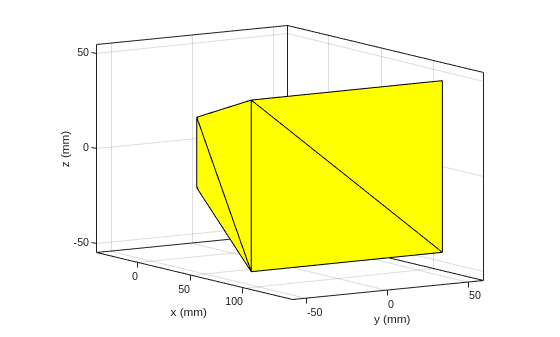

% Desired dimensions (in meters)
small_width = 45e-3;    % 45mm small opening (E-plane)
small_height = 37e-3;   % 37mm small opening (H-plane)  
large_width = 118e-3;   % 118mm large opening (E-plane)
large_height = 90e-3;   % 90mm large opening (H-plane)
horn_length = 108e-3;   % 108mm length

% Calculate scaling factors
scale_width = large_width / small_width;    % Scaling in X-direction
scale_height = large_height / small_height; % Scaling in Y-direction

% Create the horn using correct dimensions
rect1 = shape.Rectangle(Length=small_width, Width=small_height);
hornTaper1 = extrudeLinear(rect1, horn_length, Scale=[scale_width, scale_height], NumSegments=1, Caps=true);

% Position and orient the horn correctly
rotate(hornTaper1, 90, [0 0 0], [0 1 0]);  % Rotate 90° around Y-axis
rotate(hornTaper1, 90, [0 0 0], [1 0 0]);  % Rotate 90° around Y-axis

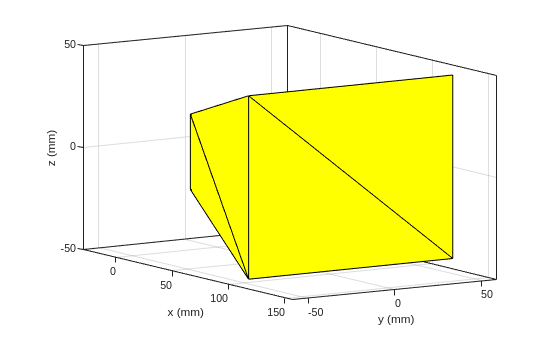


translate(hornTaper1, [waveguide_height/2, 0, 0]);  % Position for proper alignment

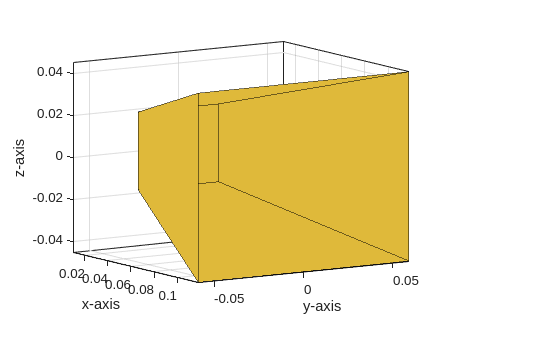


% Remove the back face if needed for waveguide connection
removeFaces(hornTaper1, 2);  % Remove the large face 

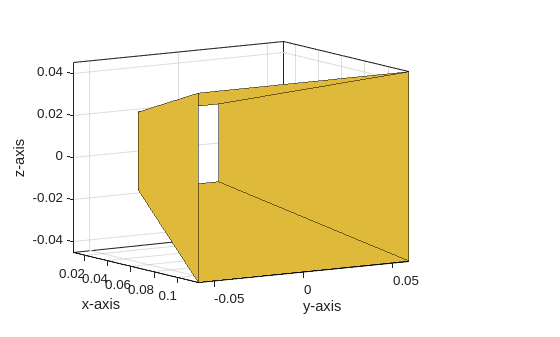

removeFaces(hornTaper1, 5);  % Remove the small face 

figure

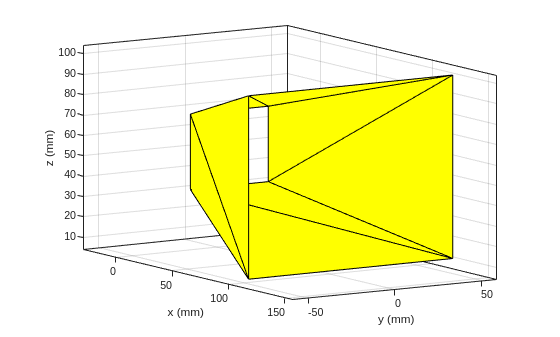

show(hornTaper1)

### Add Waveguide

Add waveguide to the tapered horn shape.

hornShape = add(wShape,hornTaper1);

Form holes along the flare length.

figure
show(hornShape)


## Integrate Feed and Analyze Antenna

The final steps involve integrating the feed mechanism and analyzing the antenna's scattering parameters over 8 GHz - 12 GHz frequency range.

Create a rectangular shape for the feed probe.

fo = -7.5e-3;
feedProbe1 = shape.Rectangle(Length=0.00508,Width=0.0014);
feedProbe = copy(feedProbe1);
show(feedProbe)

Create the perforated horn antenna by assigning the custom perforated shape created in previous steps to the `Shape` property of the `customAntenna` object.

feedProbe2 = shape.Rectangle(Length=0.0019,Width=0.0038);
[~] = translate(feedProbe2,[-feedProbe1.Length/2 0 0]);
feedProbe1 = feedProbe1 + feedProbe2;
[~] = rotateY(feedProbe1,90);
translate(feedProbe1,[fo 0 feedProbe.Length/2]);

antShape = add(hornShape,feedProbe1);
ant = customAntenna(Shape=antShape);

Add feed to the perforated horn structure using the `createFeed` function.

[~] = createFeed(ant,[fo 0 0],1);
figure
show(ant)
title("Horn Antenna");

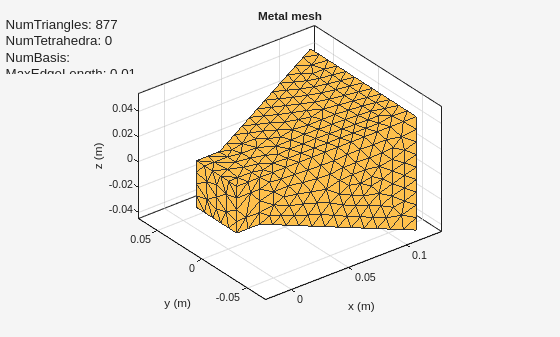

figure
mesh(ant,MaxEdgeLength=0.01,MinEdgeLength=0.002);

Calculate the S-parameters of this antenna.

s = sparameters(ant,10e9:0.5e9:25e9);
rfplot(s);

Plot the 3-D radiation pattern of this antenna.

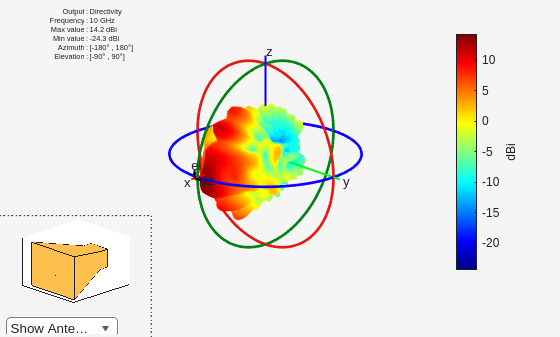

figure
pattern(ant,10e9);

Plot the 2-D azimuth and elevation patterns of this antenna. 

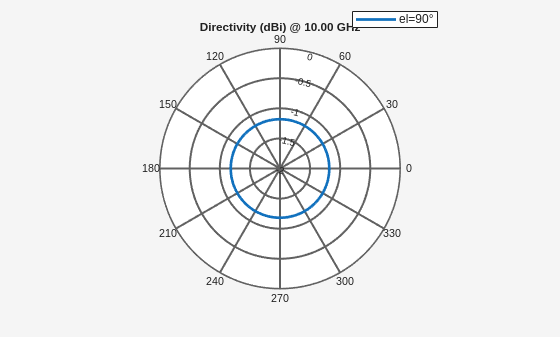

figure
patternAzimuth(ant,10e9,90);

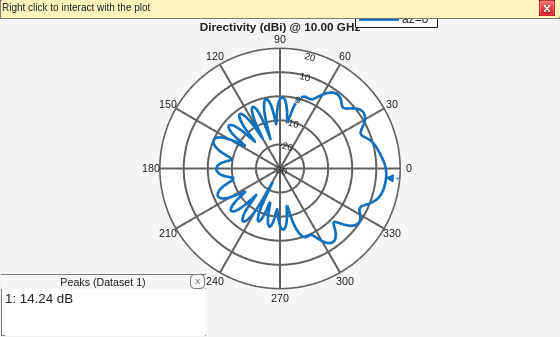

figure
patternElevation(ant,10e9);

## **Conclusion**

By meticulously following the steps outlined in this example, you can design a perforated horn antenna tailored for RF applications. The process involves constructing the basic shape, making precise modifications to refine the structure, and analyzing its performance to ensure it meets the desired specifications.

## **Reference**

[1] Huang, Guan-Long, Shi-Gang Zhou, Chow-Yen-Desmond Sim, Tan-Huat Chio,  and Tao Yuan. "Lightweight Perforated Waveguide Structure Realized by  3-D Printing for RF Applications." 

*Copyright 2024 The MathWorks, Inc.*